% EEGLAB history file generated on the 21-Sep-2024
% ------------------------------------------------

EEG.etc.eeglabvers = '2024.2'; % this tracks which version of EEGLAB is being used, you may ignore it

% rootPath = 'D:\WorkSpace\MyDataSets\BCICIV_2a_216\LRP';
rootPath = 'D:\WorkSpace\MyDataSets\BCICIV_2a_216\CZC';
savefolderPath = 'D:\WorkSpace\SelfDataSet\BCICIV_2a_mat_216\'

savefolderPath = 'D:\WorkSpace\SelfDataSet\BCICIV_2a_mat_216\'

Daypath = 'D2\';
fileInfo = dir(fullfile(rootPath, Daypath,'run*_Raw_Data.mat'));
disp(fileInfo)

  包含以下字段的 6×1 struct 数组:

    name
    folder
    date
    bytes
    isdir
    datenum




% 提取文件名
fileNames = {fileInfo.name};

filesPath = {};
for sub = 1:length(fileNames)
    filesPath{sub} = fullfile(rootPath, Daypath, fileNames{sub});
end

EEG = pop_loadbva(filesPath{1});

Importing data
Importing channel location information
Importing events
eeg_checkset note: creating the original event table (EEG.urevent)


EEG=pop_chanedit(EEG, 'changefield',{64,'labels','FCz'}); % 将lz通道改名为FCz
EEG=pop_chanedit(EEG, 'changefield',{64,'theta','0'},'changefield',{64,'radius','0.17222'},'changefield',{64,'X','0.37049'},'changefield',{64,'Y','0'},'changefield',{64,'Z','0.85717'},'changefield',{64,'sph_phi','59'},'changefield',{64,'sph_theta','0'},'changefield',{64,'radius','0.125'}); % 更改FCz坐标
% EEG = pop_select( EEG,'channel',{'FC1','Fz','C3','CP1','Pz','CP2','Cz','C4','FC2','FC3','C1','C5','CP3','P1','POz','P2','CPz','CP4','C6','C2','FC4','Iz'});
%  更改不能改变顺序

EEG = pop_select( EEG, 'channel',{'Fz','FC1','C3','CP1','Pz','CP2','Cz','C4','FC2','FC3','C1','C5','CP3','P1','POz','P2','CPz','CP4','C6','C2','FC4','FCz'}); % 只保留需要的2a数据集的22个EEG通道

Removing 45 channel(s)...


if EEG.srate ~= 250
    EEG = pop_resample( EEG, 250); % 降采样到250/sec
    disp('采样率更改为250/sec')
else
    disp('采样率为250/sec')
end

resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 
resampling event latencies...
resampling finished


pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.5 Hz
pop_eegfiltnew() - passband edge(s): [0.5 32] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.25 32.25] Hz


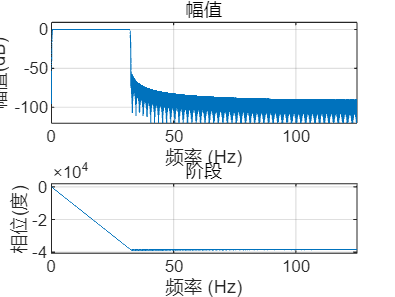

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EEG = pop_eegfiltnew(EEG, 'locutoff',0.5,'hicutoff',32,'plotfreqz',1); % 带通滤波的频带为(0.5~32)

% 从EEG结构体中提取 'data', 'event', 'chanlocs'等字段
eegdata_Raw = EEG.data;
event_Raw = EEG.event;
originalchs = EEG.chanlocs;

% 定义要筛选的标签及其对应的数字
type_map = containers.Map({'S 10', 'S 20', 'S 30', 'S 40'}, [1, 2, 3, 4]);

% 筛选出包含特定标签的结构体元素
selected_tags = {'S 10', 'S 20', 'S 30', 'S 40'};
filtered_events = event_Raw(ismember({event_Raw.type}, selected_tags));

% 为筛选后的结构体数组添加新字段 'label' 并赋值
for i = 1:length(filtered_events)
    if type_map.isKey(filtered_events(i).type)
        filtered_events(i).label = type_map(filtered_events(i).type);
    else
        filtered_events(i).label = NaN; % 如果没有匹配的类型，可以赋值为 NaN 或其他适当的值
    end
    % 对 'latency' 字段数据进行取整
    filtered_events(i).latency = round(filtered_events(i).latency);
end

% 创建一个新的结构体数组 event_tmp，只包含 label 和 latency 字段
event = struct('label', {}, 'latency', {});

% 遍历 filtered_events，将 label 和 latency 字段的值赋给 event_tmp
for i = 1:length(filtered_events)
    event(i).label = filtered_events(i).label;
    event(i).latency = filtered_events(i).latency;
end

% 显示筛选、添加新字段并取整后的结构体数组
disp(event);

  包含以下字段的 1×48 struct 数组:

    label
    latency



event_duration = 1000; % 样本数,本代码共保存1000/250=4s的数据

data = {};
indicesToKeep = {};

% 初始化 data 和 eeglabel_tmp
j = 1;
num_events = length(event); % 假设 event 是一个结构体数组
max_duration = size(eegdata_Raw, 2); % 假设 eegdata_Raw 是一个 2D 矩阵
data_tmp = zeros(num_events, size(eegdata_Raw, 1), event_duration); % 预分配空间
eeglabel_tmp = zeros(num_events, 1); % 预分配空间

for i = 1:num_events
    if any(event(i).label == [1, 2, 3, 4])
        % 确保不会超出 eegdata_Raw 的边界
        start_idx = event(i).latency;
        end_idx = min(start_idx + event_duration - 1, max_duration);
        
        % 提取数据片段
        data_tmp(j, :, 1:end_idx - start_idx + 1) = eegdata_Raw(:, start_idx:end_idx);
        
        % 存储标签
        eeglabel_tmp(j) = event(i).label;
        
        % 更新索引
        j = j + 1;
    end
end

% 移除未使用的空间（如果有必要）
data_tmp = data_tmp(1:j-1, :, :);
eeglabel_tmp = eeglabel_tmp(1:j-1);

% % 显示结果
% disp(data_tmp);
% disp(eeglabel_tmp);